%Initial Conditions
%Pressure
Psa = 100;           %systemic arteries pressure (mmHg)
Psv = 2;             %systemic veins pressure (mmHg)
Ppa = 15;            %pulmonary arteries pressure (mmHg)
Ppv = 5;             %pulmonary veneous pressure (mmHg)
PLV = 5;             %left ventricular pressure (mmHg)
PRV = 5;             %right ventricular pressure (mmHg)

%Volumes 
Vsa=1;            %systemic arteries volume (Liters)
Vsv=3.5;          %systemic veins volume (Liters)
Vpa=0.1;          %pulmonary arteries volume (Liters)
Vpv=0.4;          %pulmonary veneous volume (Liters)
VLV=0;            %left ventricular volume (Liters)
VRV=0;            %right ventricular volume (Liters)

%Initial Parameters

Rs=17.5;          %Systemic Resistance (mmHg/(L/min)
Rp=1.79;          %Pulmonary Resistance (mmHg/(L/min)
Rmv=0.01;         %Mitral Valve Resistance (mmHg/(L/min)
Rav=0.01;         %Aortic valve Resistance (mmHg/(L/min)
Rtv=0.01;         %Tricuspid valve Resistance (mmHg/(L/min)
Rpv=0.01;         %Puilmonary valve Resistance (mmHg/(L/min)

Csa=0.01;         %Systemic Arterial compliance (L/mmHg)
Cpa=0.004;        %pulmonary Arterial compliance (L/mmHg)
Csv=1.75;         %Systemic veneous compliance (L/mmHg)
Cpv=0.08;         %Pulmonary veneous compliance (L/mmHg)

%Time (min) and Flow (L/min) 
T=0.0125;         %Duration of the heartbeat (minutes)
ts=0.005;         %Duration of systole (contraction)
tmax=0.002;       %Time at which flow is max (minutes)
Qmax=14.14;

dt=0.0001;           %time step (min)
nsteps=0:dt:25*T;    % Vectorized time (min)

%Left/Right Heart Compliance Parameters
tauS=0.0025;      %min
tauD=0.0075;      %min

CLVS=0.00003;     %Min systolic value of CLV (L/mmHg)
CLVD=0.0146;      %Max diastolic value of CLV (L/mmHg)
CRVS=0.0002;      %Min systolic value of CRV (L/mmHg)
CRVD=0.0365;      %Max diastolic value of CRV (L/mmHg)

SYSTEMIC ARTERIES ISOLATION:


$$\frac{\mathrm{dPsa}}{\mathrm{dt}}=\frac{\left(\mathrm{Sao}\times \frac{\mathrm{PLV}-\mathrm{Psa}}{\mathrm{Rao}}-\frac{\mathrm{Psa}-\mathrm{Psv}}{\mathrm{Rs}}\right)}{\mathrm{Csa}}$$


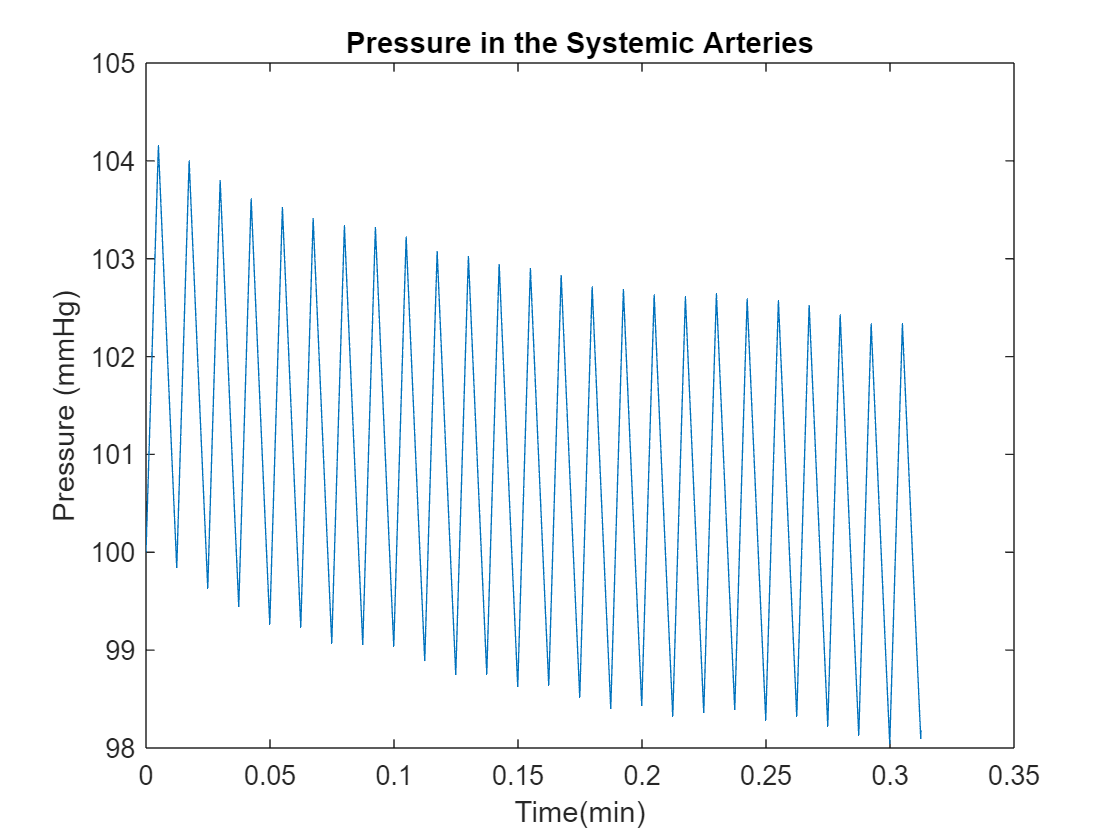

%% Solve Diff Eq
for k=1:length(nsteps)-1 % Go from beginning of time to end
 t=k*dt; % Increment of time increase
QL=Qsquarewave(t,Qmax,T,ts); % Flow rate at any given point in time
 Psa(k+1)=Psa(k)+dt*(QL-Psa(k)/Rs)/Csa; % Pressure at any given point in time
end


plot(nsteps,Psa)
title('Pressure in the Systemic Arteries')
xlabel('Time(min)')
ylabel('Pressure (mmHg)')

Pulmonary Veneous

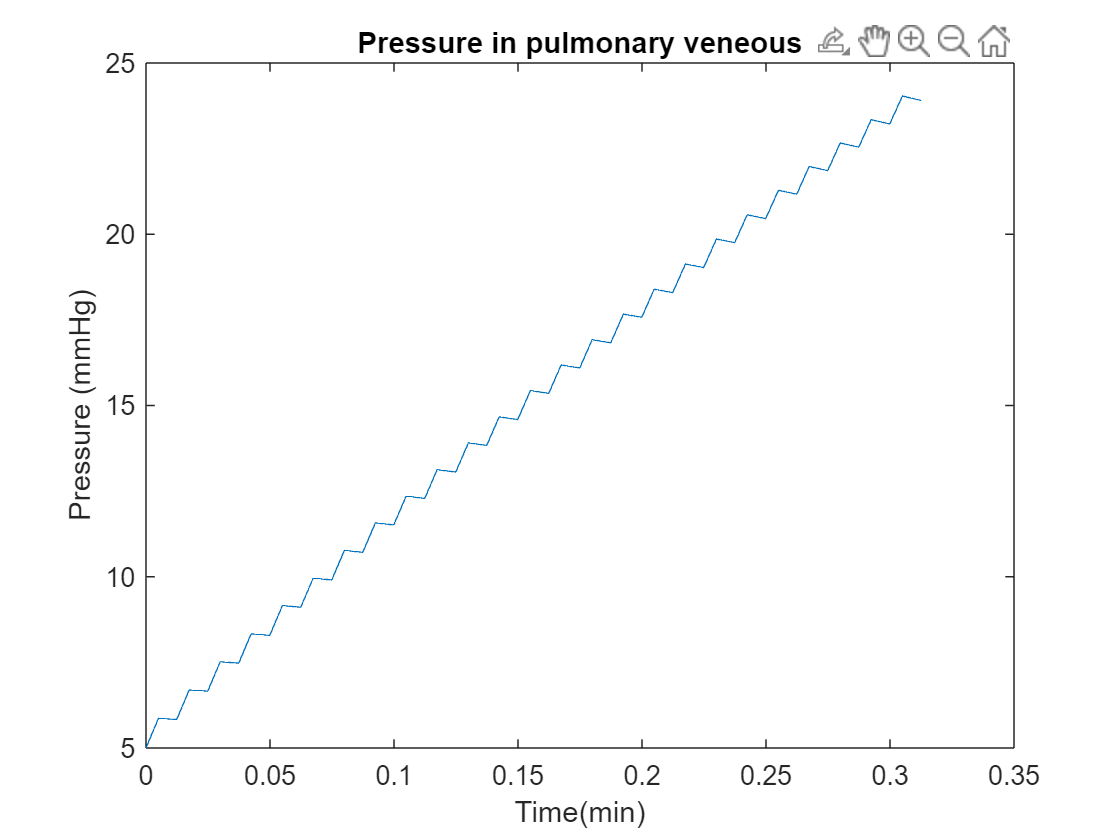

%% Solve Diff Eq
for k=1:length(nsteps)-1 % Go from beginning of time to end
 t=k*dt; % Increment of time increase
Qp=Qsquarewave(t,Qmax,T,ts); % Flow rate at any given point in time
 Ppv(k+1)=Ppv(k)+dt*(Qp-Ppv(k)/Rs)/Cpv; % Pressure at any given point in time
end
plot(nsteps,Ppv)
title('Pressure in Pulmonary Veneous')
xlabel('Time(min)')
ylabel('Pressure (mmHg)')